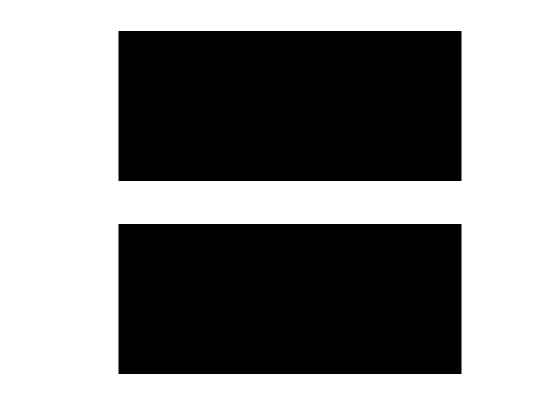

F = [zeros(56, 128); ones(16, 128); zeros(56, 128)];
G = F';
H = F + 2 * G;
showgrey(F);

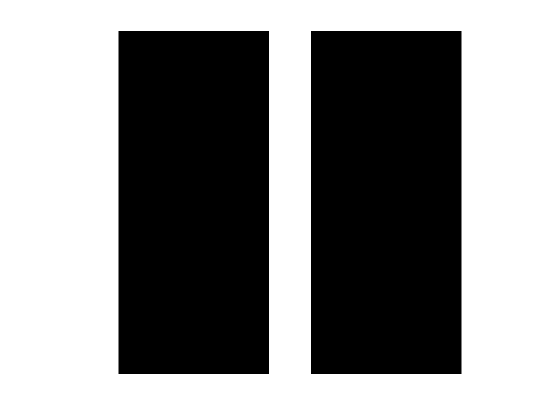

showgrey(G);

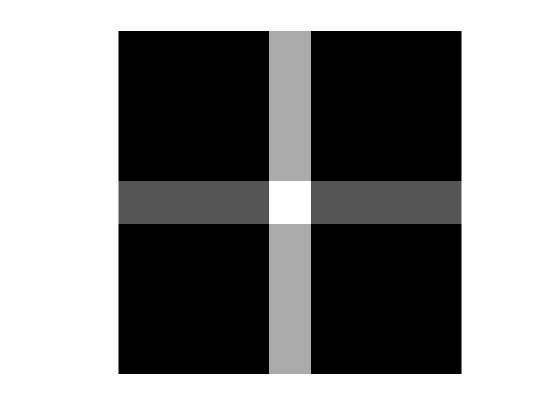

showgrey(H);

ans = 6144

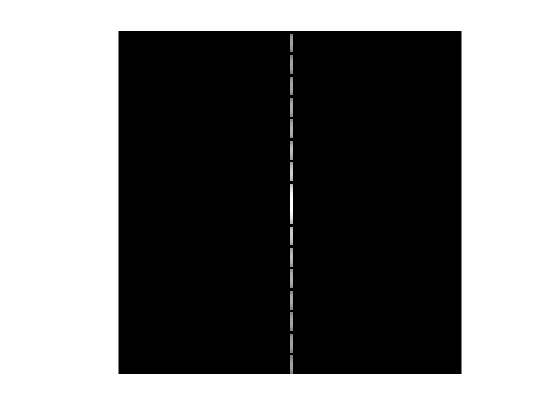

Fhat = fft2(F); 
Ghat = fft2(G);
Hhat = fft2(H);

showgrey(log(1+abs(fftshift(Fhat))));

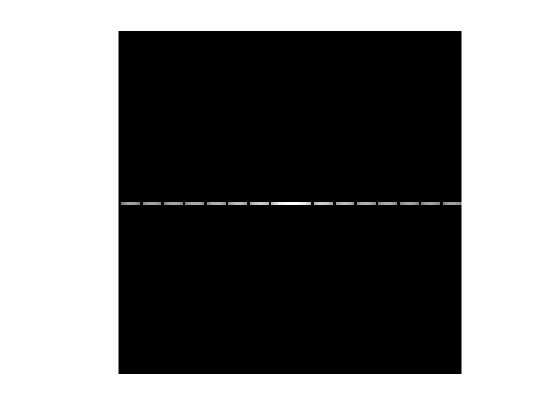

showgrey(log(1+abs(fftshift(Ghat))));

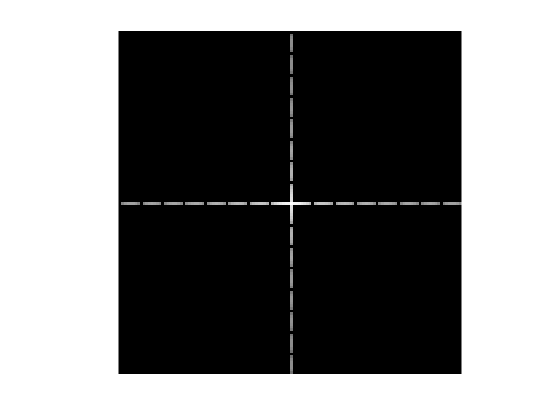

showgrey(log(1+abs(fftshift(Hhat))));


showgrey(log(1 + abs(fftshift(Fhat + 2*Ghat))));

all(all(Fhat + 2*Ghat == Hhat)) == 1

ans = logical
   1
